%define grid spacing for vector fields
vgrid = 1.0/3.0;
%define grid spacing for scalar fields
sgrid = 1.0/3.0;

%Define function of interest as anonymous functions
%leave only 1 function uncommented
%f = @(x,y) x^2 + y^2;
%f = @(x,y) -0.2*y^3 + 0.1*x^2*y + 0.4*x^2;
f = @(x,y) cos(2*x)*cos(2*y);
%f = @(x,y) 1/(x*y)

%Define meshes for 2d scalar and vector fields
[Xs,Ys] = meshgrid(-2:sgrid:2,-2:sgrid:2);
[Xv,Yv] = meshgrid(-2:vgrid:2,-2:vgrid:2);

%Choose one function to be the main function to be plotted
%arrayfun applies the anonymous function to matrices
Fs = arrayfun(f,Xs,Ys);
Fv = arrayfun(f,Xv,Yv);

Plot the surface z = f(x,y) using the `surf command`.

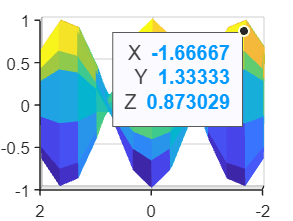

%doc surf
surf(Xs,Ys,Fs,EdgeColor="none");

Plot the level curves, aka the contour map, experimenting with different options to

• Fill in the contours with colour.

• Change the number of level curves / contours.

• Display the surface and contour map simultaneously via `surfc`.

• Display the contours in 3d via `contour3`.

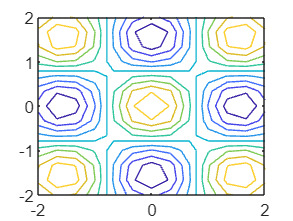

contour(Xs,Ys,Fs);

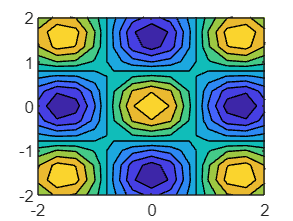

contourf(Xs,Ys,Fs);

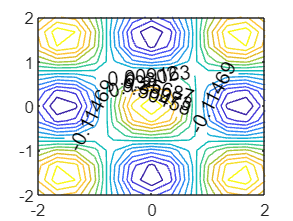

[C, h] = contour(Xs,Ys,Fs,15);
clabel(C,h)

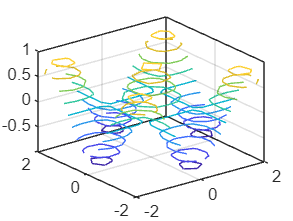

contour3(Xs,Ys,Fs);

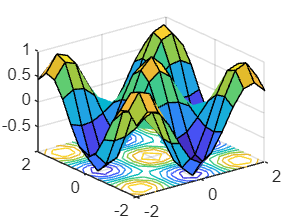

surfc(Xs,Ys,Fs);

## Calculating and plotting the gradient of a scalar field

Remember: the gradient vector field ∇f points in the direction of steepest increase, and has magnitude equal to the

rate of increase.

In this subsection you will be able to see this in action by combining what you have seen of f(x,y) via surface and

contour plots, together with a `quiver` plot of ∇f(x,y).

To calculate the gradient use the `gradient` function, and plot the result using quiver. Note: here we are using the

vector grid.

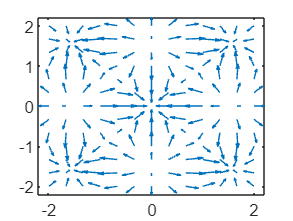

[DX,DY]=gradient(Fv,vgrid);
quiver(Xv,Yv,DX,DY)

To get a real sense for how the level curves and gradient are related you should plot them on the same graph. For

example

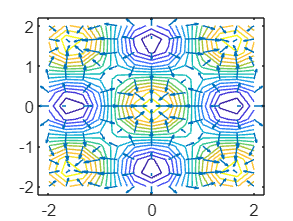

%Plotting gradient and contour on the same graph
contour(Xs,Ys,Fs,15);
hold on
[DX,DY]=gradient(Fv,vgrid);
quiver(Xv,Yv,DX,DY)
hold off